clear
close
clc

numProve=6;

for ii=1:numProve
    
    dati=readmatrix(ii+".xlsx");
    Tf(ii)=dati(end,2);
    Ti(ii)=dati(1,2)+1;
    Data{ii}=dati(:,2).*(dati(:,2)>dati(1,2)+0.1);
    
    kk=1;
    for jj=1:length(Data{ii})
        
        if(Data{ii}(jj)~=0)
            Data{ii}(kk)=Data{ii}(jj);
            kk = kk + 1;
        end
        
    end
    
end

Tc = 0.1;
tau=zeros(1,numProve);
min=zeros(1,numProve);

scelta=4;

%======= Costante di tempo per sistema primo ordine ==========

% Determino tau con 4 metodi differenti, poi ne faccio la media

% Determino tau col metodo grafico


%identifico il valore tra i dati aquisiti con minore differenza dal valore
%atteso al tempo tau

for ii = 1:numProve
    min(ii) = abs(Data{ii}(ii) -Tf(ii)-(Ti(ii) - Tf(ii))*0.368);
end

for ii = 1:numProve
    for time = 1:length(Data{ii}(:,1))
        if abs(Data{ii}(time,1) -Tf(ii)-(Ti(ii) - Tf(ii))*0.368)< min(ii)
           min(ii) = abs(Data{ii}(time) -Tf(ii)-(Ti(ii) - Tf(ii))*0.368);
           tau(ii) = time*Tc;
        end
    end
end

tau

tau =    93.2000   98.0000   94.5000   98.6000   98.0000   99.4000


Tau1 = mean(tau)

Tau1 = 96.9500

% Display del grafico
Ttau=zeros(1,numProve);
for ii = 1:numProve
    Ttau(ii) = Tf(ii)+(Ti(ii) - Tf(ii))*0.368;
end
Ttau

Ttau =   328.7213  330.0972  329.5921  333.1004  331.9012  330.1113


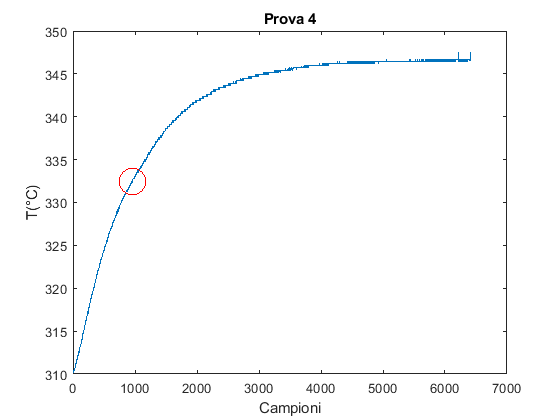


figure;
plot(Data{scelta});
hold on;
title("Prova "+scelta);
ylabel("T(°C)")
xlabel("Campioni")
plot(ceil(tau(scelta)/Tc),Data{scelta}(ceil(tau(scelta)/Tc),1),'Color',[1 0 0],"MarkerSize",20,"Marker","o")

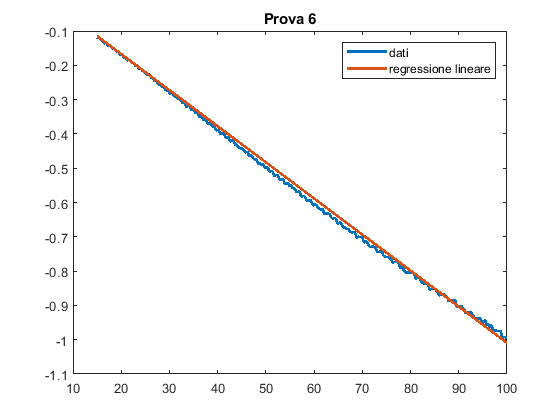

% secondo metodo
% linearizzo l'equazione e tramite il coefficiente valuto tau

a=zeros(2,numProve);   %coefficienti
%filtro
[B,A]=butter(4,0.3,"low");
for ii=1:numProve
    filtrato=filter(B,A,Data{ii});
    X{ii}=(150:1000)*Tc;
    Y{ii}=log((filtrato(150:1000)-Tf(ii))/(Ti(ii)-Tf(ii)));
    a(:,ii)=polyfit(X{ii},Y{ii},1);
    tau(ii)=-1/a(1,ii);
end

figure;
plot(X{scelta},Y{scelta},'LineWidth',2);
title("Prova "+ii);

hold on;
plot(X{ii},a(1,ii)*X{ii}+a(2,ii),'LineWidth',2);
legend("dati","regressione lineare")


tau

tau =    89.6640   92.0419   88.6419   95.7775   91.6249   94.9989


Tau2=mean(tau)

Tau2 = 92.1248

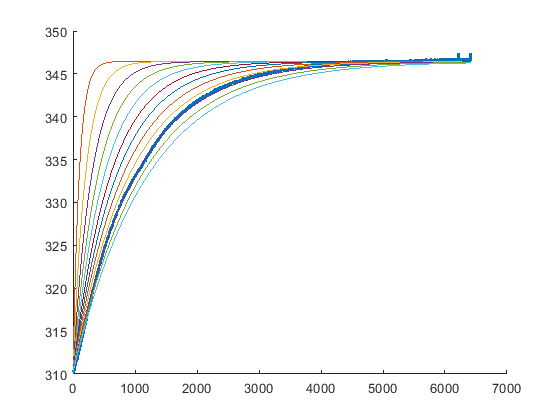

%terzo metodo
tot=0;
for ii = 1:numProve
    for time = 1:length(Data{ii}(:,1))
            min(ii)=min(ii)+power(Data{ii}(time) ...
                -Tf(ii)-(Ti(ii) - Tf(ii))*power(exp(1),-time*Tc/1),2);
    end
end


figure;

for ii = 1:numProve
    
    if ii==scelta
        hold on;
        plot(Data{ii},'LineWidth',2);
    end
    

    for tauVar=10:1:120
        
        tot=0;
        for time = 1:length(Data{ii}(:,1))
            tot=tot+power(Data{ii}(time) ...
                -Tf(ii)-(Ti(ii) - Tf(ii))*power(exp(1),-time*Tc/tauVar),2);
            
            if ii==scelta
                            y(time)=Tf(ii)+(Ti(ii) ...
                                - Tf(ii))*power(exp(1),-time*Tc/tauVar);
            end

        end
        
        if mod(tauVar,10)==0 && ii==scelta
            hold on;
            plot(y);
        end
      
        if tot< min(ii)
                min(ii) = tot;
                tau3(ii) = tauVar;
        end
        
    end
    
end


tau3

tau3 =     96   104    99    99   100   102


Tau3 = mean(tau3)

Tau3 = 100

%quarto metodo

for ii=1:numProve
    for time=1:length(Data{ii})
        tauVar2(time)=time*Tc/log( abs( (Ti(ii)-Tf(ii)) / (Data{ii}(time)-Tf(ii)) ) );
    end
    tau4(ii)=mean(tauVar2);
end

tau4

tau4 =    91.9827  114.5914   96.8996   80.0439   95.6320   92.7215


Tau4=mean(tau4)

Tau4 = 95.3119

%media delle medie


Tau1

Tau1 = 96.9500

Tau2

Tau2 = 92.1248

Tau3

Tau3 = 100

Tau4

Tau4 = 95.3119


TAUtot=(Tau1+Tau2+Tau3+Tau4)/4

TAUtot = 96.0967

t7 =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


y =          0    0.1494    0.2955    0.4350    0.5646    0.6816    0.7833    0.8674    0.9320    0.9757    0.9975    0.9969    0.9738    0.9290    0.8632    0.7781    0.6755    0.5577    0.4274    0.2875    0.1411   -0.0084   -0.1577   -0.3035   -0.4425   -0.5716   -0.6878   -0.7885   -0.8716   -0.9351   -0.9775   -0.9981   -0.9962   -0.9719   -0.9258   -0.8589   -0.7728   -0.6692   -0.5507   -0.4198   -0.2794   -0.1328    0.0168    0.1660    0.3115    0.4500    0.5784    0.6938    0.7937    0.8757